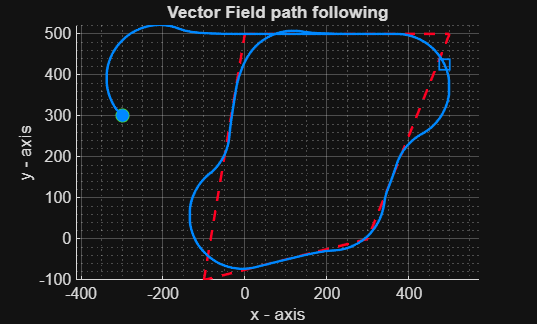

clear;
clc;

%Time definition
sim_time = 200;
dt = 0.001;


%Path definition
d0 = [0, 500];
d1 = [500, 500];
d2 = [300, 0];
d3 = [-100, -100];
d4 = [0, 500];

lines = [d0,(d1-d0)/norm(d1-d0), d1;
      d1,(d2-d1)/norm(d2-d1), d2;
      d2,(d3-d2)/norm(d3-d2), d3;
      d3,(d4-d3)/norm(d4-d3), d4;
      ];


figure;
hold on;
grid on; grid minor;
axis equal;
xlabel("x - axis");
ylabel("y - axis");
title("Vector Field path following");

for line=lines'
    plot([line(1), line(5)], [line(2), line(6)],"--", lineWidth=1.5, color="#ff0022");
end

%curvature constraint definition
g = 9.81;
phi_max = pi/3;


%UAV definition
vg = 15;
p0 = [-300, 300];
chi = 3*pi/4;
chi_inf = pi/2;


% gains
alpha = 1.65; %i guess will be predefined

k = 0.03;
kappa = pi/2;

epsilon = 0.1;


state = zeros([sim_time/dt + 1, 7]);
state(1, :) = [p0,chi, 0, 0, 0, 0];

plot(state(1,1), state(1, 2), 'o', markersize=8, MarkerFaceColor='#0088ff');


%curvature constraint definition
chi_dot_max = tan(phi_max)/vg;

switch_distance = vg/chi_dot_max;

%first line selection
min_dist = inf;
c_line = 1;
i = 1;
for line=lines'
    dist = norm(cross([p0-line(1:2)', 0], [line(3:4)', 0]));
    if  dist < min_dist
        min_dist = dist;
        c_line = i;
    end
    i = i + 1;
end


i = 2;
for t=dt:dt:sim_time
    %calculation for previous step
    chi = state(i-1, 3);
    dist = cross([state(i-1, 1:2) - lines(c_line,1:2), 0], [lines(c_line, 3:4), 0]);
    y = -dist(3);

    chi_d = wrapToPi(atan2(lines(c_line, 4), lines(c_line, 3)) - chi_inf*(2/pi)*atan(k*y));
    chi_tilda = wrapToPi(chi - chi_d);
    chi_c = wrapToPi(chi - (1/alpha)*chi_inf*(2/pi)*(k/(1+ (k*y)^2))*vg*sin(chi) - (kappa/alpha)*sat(chi_tilda/epsilon));
    
    chi_dot = max(min(alpha*wrapToPi(chi_c - chi), chi_dot_max), -chi_dot_max);
    
    state(i-1, 4:7) = [chi_dot, chi_c, chi_d, y];

    %calculation for this step
    chi = chi + chi_dot * dt;
    
    state(i, 1) = state(i-1, 1) + vg*cos(chi)*dt;
    state(i, 2) = state(i-1, 2) + vg*sin(chi)*dt;
    state(i, 3) = chi;

    if norm(lines(c_line, 5:6) - state(i, 1:2)) < switch_distance
        c_line = c_line + 1;

        if c_line > size(lines, 1)
            c_line = 1;
        end
    end
        
    if ~mod(i, 100)
        if i ~= 100
            delete(h1);
            delete(h2);

        end
      
        h1 = plot(state(1:i, 1), state(1:i, 2), lineWidth = 1.5, color = "#0088ff");
        h2 = plot(state(i,1), state(i,2), marker="square", markersize = 8, color = '#0088ff', linewidth=1.5);

        pause(dt);
    end

    i = i + 1;
end

hold off;

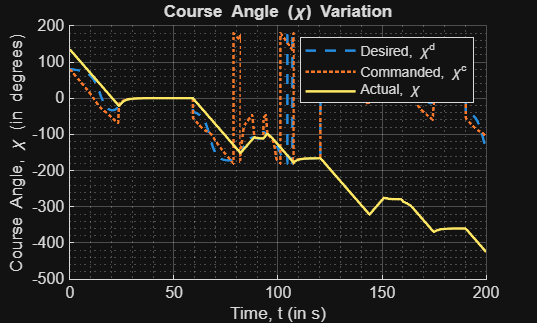


figure;
hold on;
plot(0:dt:(sim_time-dt), state(1:end-1, 6)*180/pi,"--", lineWidth=1.5);
plot(0:dt:(sim_time-dt), state(1:end-1, 5)*180/pi,lineStyle=":", lineWidth=1.5);
plot(0:dt:sim_time, state(:, 3)*180/pi, lineWidth=1.5);
grid on; grid minor;
xlabel("Time, t (in s)");
ylabel("Course Angle, \chi (in degrees)");
title("Course Angle (\chi) Variation");
legend("Desired, \chi^d", "Commanded, \chi^c", "Actual, \chi");
hold off;

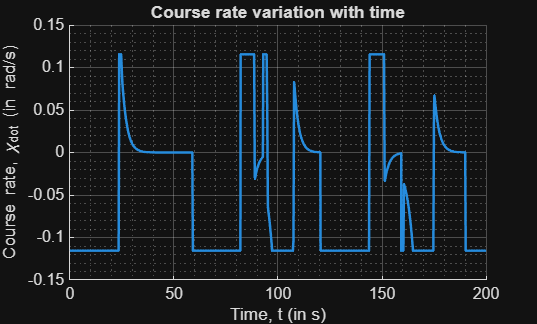


figure;
hold on;
grid on; grid minor;
plot(0:dt:(sim_time-dt), state(1:end-1, 4), lineWidth=1.5);
title("Course rate variation with time");
xlabel("Time, t (in s)");
ylabel("Course rate, \chi_d_o_t (in rad/s)");
hold off;

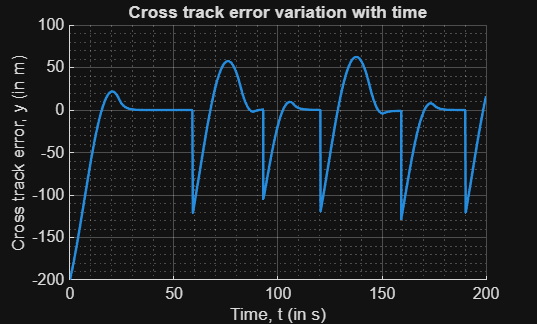


figure;
hold on;
grid on; grid minor;
plot(0:dt:(sim_time-dt), state(1:end-1, 7), lineWidth=1.5);
title("Cross track error variation with time");
xlabel("Time, t (in s)");
ylabel("Cross track error, y (in m)");
hold off;


function val = sat(x)
    if abs(x) <= 1
        val = x;
    else
        val = sign(x);
    end
end
